## 1. 画出函数图像

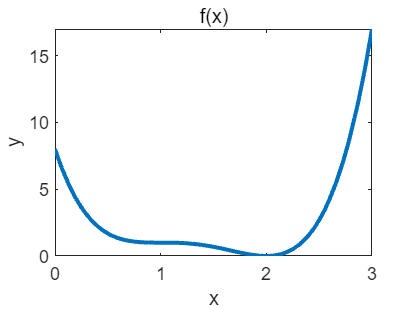

clc,clear
f=@(x)3*x.^4-16*x.^3+30*x.^2-24*x+8;
fplot(f,[0 3],'LineWidth',2)
title('f(x)')
xlabel('x');
ylabel('y');

## 2. 用二分法求该函数极小值

a=0;b=3;tol=1e-16;iter_max=10;
syms x;
df=diff(f,x);
df=matlabFunction(df);
[x,f_val,iter_time,tol_list]=binary_search_min(f,df,a,b,iter_max,tol);
disp("二分法：")

二分法：


fprintf('找到的近似零点: %.6f\n', x);

找到的近似零点: 1.999512


fprintf('函数极小值: %.6f\n', f_val);

函数极小值: 0.000001


fprintf('迭代次数: %d\n', iter_time);

迭代次数: 10


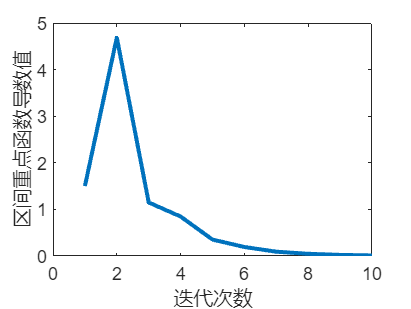

%展示算法的极小化过程
plot([1:iter_time],tol_list,'LineWidth',2)
xlabel("迭代次数")
ylabel("区间重点函数导数值")

## 3. 用三分法求该函数极小值

[x,f_val,iter_time,tol_list]=ternarySearchMin(f,a,b,iter_max,tol);
disp("三分法")

三分法


fprintf('找到的近似零点: %.6f\n', x);

找到的近似零点: 1.995986


fprintf('函数极小值: %.6f\n', f_val);

函数极小值: 0.000096


fprintf('迭代次数: %d\n', iter_time);

迭代次数: 10


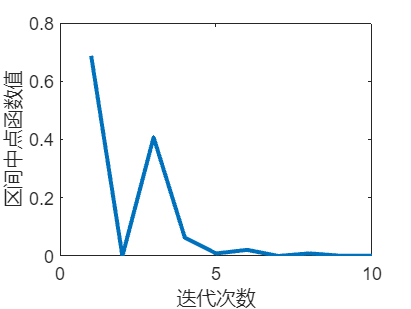

%展示算法的极小化过程
plot([1:iter_time],tol_list,'LineWidth',2)
xlabel("迭代次数")
ylabel("区间中点函数值")

## 4.用黄金分割法求该函数极小值

[x,f_val,iter_time,tol_list]=goldenSectionMin(f,a,b,iter_max,tol);
disp("黄金分割法")

黄金分割法


fprintf('找到的近似零点: %.6f\n', x);

找到的近似零点: 1.994015


fprintf('函数极小值: %.6f\n', f_val);

函数极小值: 0.000213


fprintf('迭代次数: %d\n', iter_time);

迭代次数: 10


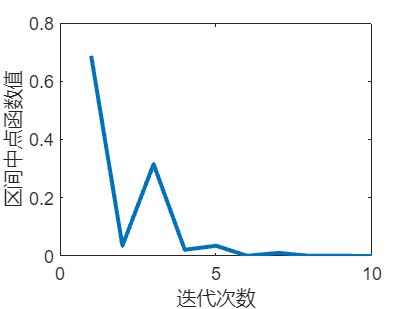

%展示算法的极小化过程
plot([1:iter_time],tol_list,'LineWidth',2)
xlabel("迭代次数")
ylabel("区间中点函数值")

## 5. 探索 Matlab 内置命令求该函数极小值

%fminbnd
%查找单变量函数在定区间上的最小值
x1 = 0;
x2 = 3;
options = optimset('Display','iter');
x = fminbnd(f,x1,x2,options)

 
 Func-count     x          f(x)         Procedure
    1         1.1459     0.988937        initial
    2         1.8541     0.104232        golden
    3         2.2918     0.731378        golden
    4        1.76686     0.233608        parabolic
    5        1.94397    0.0174569        parabolic
    6        2.07683    0.0391491        golden
    7        1.99429  0.000193919        parabolic
    8        1.99709  5.04873e-05        parabolic
    9        2.00035  7.55957e-07        parabolic
   10        2.00001  4.95803e-10        parabolic
   11        1.99998  3.53495e-09        parabolic
   12        2.00004  1.08143e-08        parabolic
 
优化已终止:
 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件



x = 2.0000

function [x_min,f_min,iter_time,tol_list]=binary_search_min(f,df,a,b,iter_max,tol)
    [x_min,iter_time,tol_list]=binarySearchZero(df,a,b, iter_max, tol);
    f_min=f(x_min);
end
function [root, iterations,tol_list] = binarySearchZero(func, a, b, iter_max, tol)  
    if nargin < 5
        tol = 1e-6; % 默认容差
    end
    if nargin < 4
        iter_max = 1000; % 默认迭代次数
    end
    fa = func(a);
    fb = func(b);
    tol_list=[];
    if fa * fb > 0
        error('函数在给定区间端点处没有根');
    end
    iterations = 0;
    while iterations < iter_max
        iterations = iterations + 1;
        c = (a + b) / 2;
        fc = func(c);
        tol_list=[tol_list,abs(fc)];
        if abs(fc) < tol
            root = c;
            return;
        end
        if fa * fc < 0
            b = c;
            fb = fc;
        else
            a = c;
            fa = fc;
        end
    end
    root = (a + b) / 2;
end

function [xmin,fmin,iterations,tol_list] = ternarySearchMin(func, a, b, iter_max, tol)
    if nargin < 5
        iter_max = 1000; % 默认迭代次数
    end
    if nargin < 4
        tol = 1e-6; % 默认容差
    end
    tol_list=[];
    iterations = 0;
    while (b - a) > tol && iterations < iter_max
        iterations = iterations + 1;    
        % 计算两个切分点
        m1 = a + (b - a) / 3;
        m2 = b - (b - a) / 3;
        % 计算函数在切分点处的值
        fm1 = func(m1);
        fm2 = func(m2);
        tol_list=[tol_list,abs(func((m1+m2)/2))];
        if fm1 < fm2
            b = m2; % 更新搜索区间
        else
            a = m1; % 更新搜索区间
        end

    end
    xmin = (a + b) / 2;
    fmin = func(xmin);
end
function [xmin, fmin, iterations,tol_list] = goldenSectionMin(func, a, b, iter_max, tol)
    goldenRatio = (sqrt(5) - 1) / 2; % 黄金比例
    
    if nargin < 5
        iter_max = 1000; % 默认迭代次数
    end
    if nargin < 4
        tol = 1e-6; % 默认容差
    end
    tol_list=[];
    iterations = 0;
    while (b - a) > tol && iterations < iter_max
        iterations = iterations + 1;
        m1 = b - goldenRatio * (b - a);
        m2 = a + goldenRatio * (b - a);
        fm1 = func(m1);
        fm2 = func(m2);
        tol_list=[tol_list,abs(func((m1+m2)/2))];
        if fm1 < fm2
            b = m2; 
        else
            a = m1; 
        end
    end
    xmin = (a + b) / 2;
    fmin = func(xmin);
end
